# CÁLCULO NUMÉRICO

# PRÁCTICA 5 · TEMA 7 · INTEGRACIÓN

## P05_T07_P01. Método compuesto de los trapecios

a) (1,25p) Escribir una función Matlab que utilice el método compuesto de los trapecios para la integración de una función  que se da en forma analítica (ecuación). Para el nombre de la función y los argumentos utiliza 

`I = Compzoidal(Fun,a,b,Er)`. 

`Fun` es un nombre para la función que se está integrando. La función real que se integra debe escribirse como una función anónima o definida por el usuario que calcula, mediante operaciones elemento por elemento, los valores de  para valores dados de . `a` y `b` son los límites de la integración, e `I `es el valor de la integral.  La función `Compzoidal` calcula el valor de la integral en iteraciones. En la primera iteración el intervalo  se divide en dos subintervalos.  En cada iteración, el número de subintervalos se duplica. Las iteraciones se detienen cuando la diferencia del valor de la integral entre dos iteraciones sucesivas es menor que `Er`.

b) (0,75p) Emplea la función creada en el apartado a) para resolver el siguiente problema:

La fuerza $f$ por unidad de longitud expresada en $\frac{\mathrm{lb}}{\mathrm{ft}}$ que ejerce el viento sobre una vela de 24 pies de altura en función de su altura $z$ viene dada por: $f=160\frac{z}{z+4}e^{-\frac{z}{8}}$

La fuerza total en la vela se calcula mediante: $F=\int_0^{24} f\left(z\right)\;\;\textrm{dz}$

Calcula la fuerza total con un error menor que 0.001

### Respuesta

Fun = @(z) 160 .* (z ./ (z+4)).*exp((- z./8));
a = 0;
b = 24; 
Er = 0.001;

I = Compzoidal(Fun, a, b, Er);
fprintf('La fuerza total de la vela es: %.4f lb/ft', I);

La fuerza total de la vela es: 632.9651 lb/ft

## P05_T07_P02. Método de Simspon puntos discretos

a) (1,25p) Escribir una función Matlab para la integración con el método compuesto de Simpson de una función $f\left(x\right)$ que se da mediante un conjunto de $n$ puntos discretos que están espaciados por igual. Para el nombre y los argumentos de la función utiliza 

`I = PuntosSimpson(x,y)`

donde los argumentos de entrada `x` e `y` son vectores con los valores de $x$ y los correspondientes valores de $y$, respectivamente. El argumento de salida `I` es el valor de la integral. 

Si el número de intervalos de los puntos de datos es divisible por 3, la integración se hace con el método compuesto de Simpson de 3/8. Si el número de intervalos en los puntos de datos es uno más que un número divisible por 3, la integración en el primer intervalo se hace con el método trapezoidal y la integración en el resto de los intervalos se hace con el método compuesto de Simpson de 3/8. Si el número de intervalos en los puntos de datos es dos más que un número divisible por 3, entonces la integración en los dos primeros intervalos se hace con el método 1/3 de Simpson y la integración en el resto de los intervalos se hace con el método 3/8 de Simpson compuesto.

b) Emplea la función anterior para resolver la siguiente cuestión:

La curva de Lorentz, es una herramienta matemática utilizada tanto por los economistas como por los sociólogos para medir el porcentaje de la riqueza de una sociedad que posee un determinado porcentaje de sus habitantes. Para ser más específicos, la curva de Lorentz para la economía de una sociedad concreta es el gráfico de la función $L\left(x\right)$, que denota la fracción de la renta nacional anual total obtenida por el $100x%$ de los asalariados peor pagados de la sociedad, para $0\le x\le 1$. Por ejemplo, si el 30% de los asalariados peor pagados reciben el 23% de la renta total de la sociedad, entonces $L\left(0\ldotp 3\right)=0\ldotp 23$

Nótese que $L\left(x\right)$ es una función creciente en el intervalo $0\le x\le 1$y tiene estas propiedades:

- $0\le L\left(x\right)\le 1$ porque $L\left(x\right)$ es un porcentaje

- $L\left(0\right)=0$ porque no se ganan salarios cuando no se emplean asalariados

- $L\left(1\right)=1$ porque el $100\cdot x%$ de los salarios son ganados por el $100\cdot x%$ de los asalariados

- $L\left(x\right)\le x$ porque el $100\cdot x%$ de los asalariados peor pagados no pueden recibir más del $100\cdot x%$ de los ingresos totales

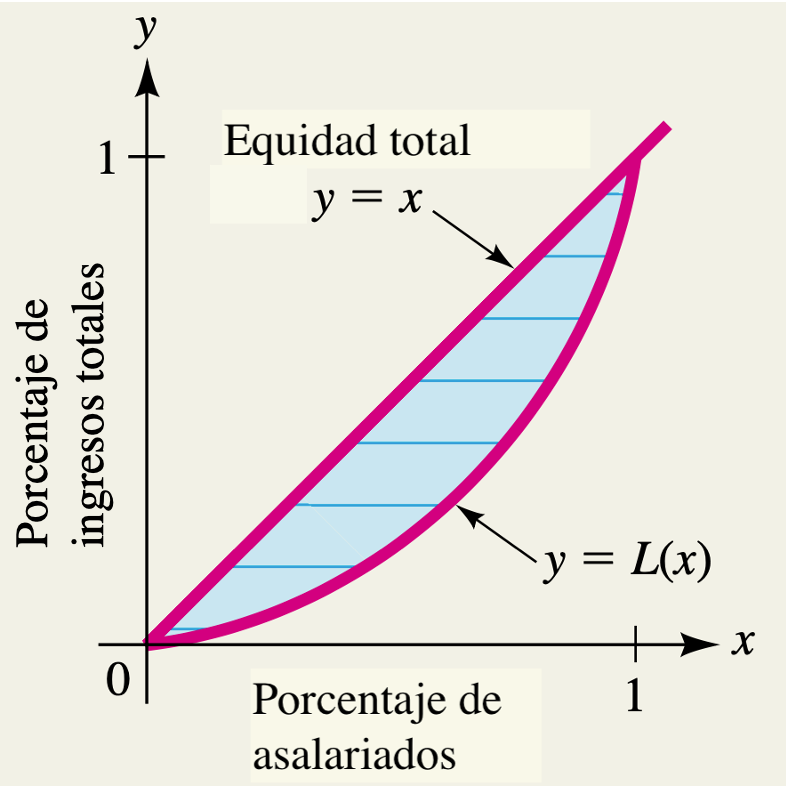                     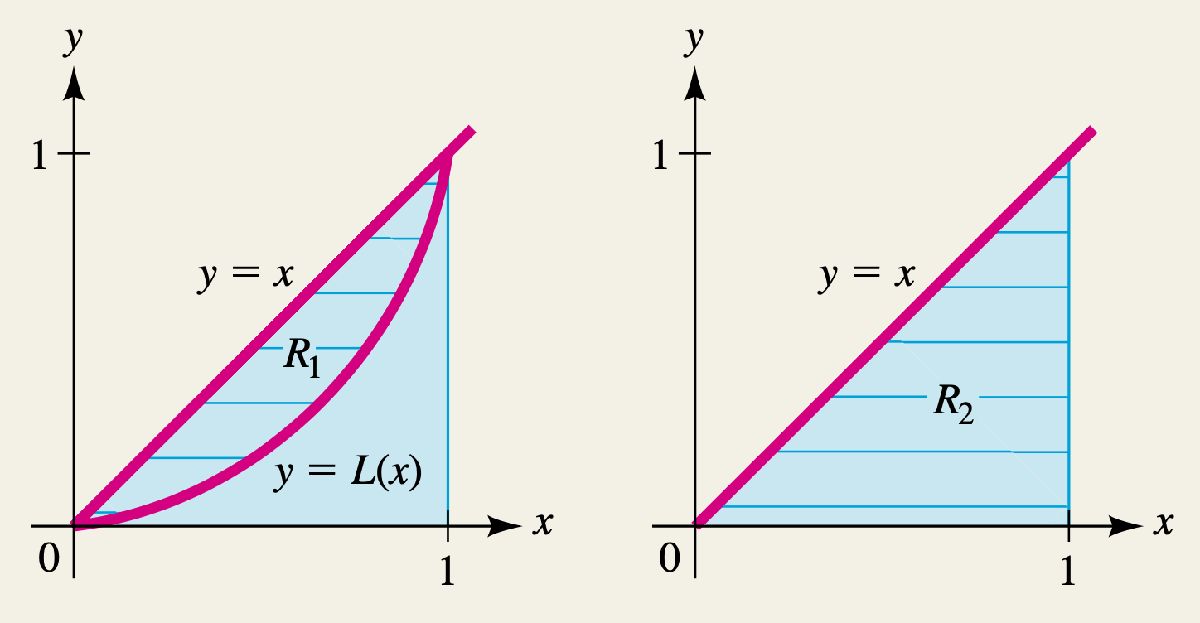

La recta $y=x$ representa el caso ideal que corresponde a una completa igualdad en la distribución de la renta (los asalariados con el $100\cdot x%$de la renta más baja reciben el $100\cdot x%$ de la riqueza de la sociedad). Cuanto más se acerque una determinada curva de Lorentz a esta recta, más equitativa será la distribución de la riqueza en la sociedad correspondiente.

La desviación total de la distribución real de la riqueza en la sociedad con respecto a la igualdad completa se representa mediante el área de la región $R_1$ entre la curva de Lorentz $y=L\left(x\right)$ y la recta $y=x$. La relación entre este área y el área de la región $R_2$ bajo la línea de igualdad completa $y=x$ en  $0\le x\le 1$ se utiliza como medida de la desigualdad en la distribución de la riqueza en la sociedad. Este cociente, denominado **índice de Gini,** denotado IG (también llamado índice de desigualdad de la renta).

El índice de Gini se sitúa siempre entre 0 y 1. Un índice de 0 corresponde a una equidad total en la distribución de la renta, mientras que un índice de 1 corresponde a una inequidad total (toda la renta pertenece al 0% de la población). Cuanto menor es el índice, más equitativa es la distribución de la renta, y cuanto mayor es el índice, más se concentra la riqueza en unas pocas manos. 

La tabla representa los porcentajes de ingresos $y$ para los porcentajes seleccionados de familias $x$ en un país:

b.1) (0,25p) Calcula el área de la región bajo la curva de Lorenz

b.2) (0,25p) Calcula el área entre la igualdad total y la curva de Lorenz

b.3) (0,25p) Calcula el índice de Gini del país correspondiente a los puntos dados

### Respuesta

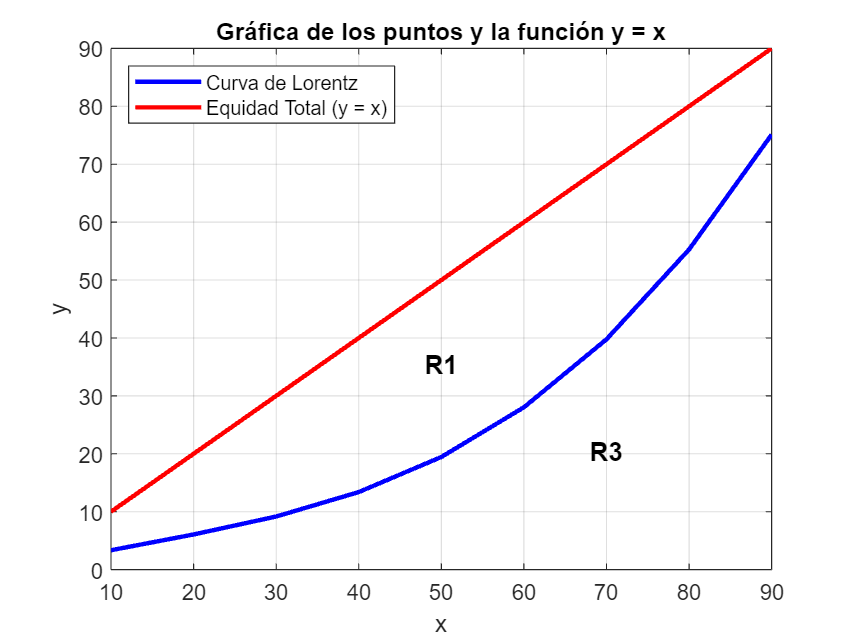

% Datos del Problema
x = 10:10:90;
y = [3.35 6.07 9.17 13.39 19.45 28.03 39.77 55.28 75.12];

% Gráfica 
plot(x, y, 'b', 'LineWidth', 2);
hold on;
plot(x, x, 'r', 'LineWidth', 2); 
xlabel('x');
ylabel('y');
title('Gráfica de los puntos y la función y = x');
legend('Curva de Lorentz', 'Equidad Total (y = x)', 'Location', 'northwest');
grid on;
text(50, 35, '\bf{R1}', 'HorizontalAlignment', 'center', 'FontSize', 12);
text(70, 20, '\bf{R3}', 'HorizontalAlignment', 'center', 'FontSize', 12);
hold off; 

#### b.1)

R3 = PuntosSimpson(x, y);
fprintf('Área bajo la Cruva de Lorentz: %.4f', R3)

Área bajo la Cruva de Lorentz: 856.1667

#### b.2)

xx = 10:10:90;
yy = 10:10:90;
EquidadTotal = PuntosSimpson(xx, yy);
R1 = EquidadTotal - R3;

fprintf('Área área entre la igualdad total y la curva de Lorenz: %.4f', R1)

Área área entre la igualdad total y la curva de Lorenz: 1193.8333

#### b.3)

IG = R1 / EquidadTotal;
fprintf('Índice de GINI: %.4f', IG)

Índice de GINI: 0.5824

## P05_T07_P03. Método de Simspon función f = @(x)

a) (1,25p) Escribe una función de MATLAB que utilice el método compuesto de Simpson 3/8 para la integración de una función que está dada en forma anónima (). Para el nombre de la función y los argumentos utiliza:

`I = Simpson38 (y, a, b, Er)`.

`y` es un nombre para la función que se está integrando dada en forma `y = @(x)` vectorizada,` a` y `b` son los límites de integración, e `I` es el valor de la integral. La función de integración calcula el valor de la integral en iteraciones. En la primera iteración el intervalo se divide en tres subintervalos. En cada iteración que sigue, el número de subintervalos se duplica. Las iteraciones se detienen cuando el error relativo entre dos iteraciones sucesivas es menor que `Er`. 

b) (0,75p) Utiliza `Simpson38` para calcular: 


$$I=\int_0^3 \sqrt{\frac{x^3 }{4-x}\;\;\textrm{dx}}$$
         

con un error de ${10}^{-4}$

Calcula el error relativo en % tomando como valor real el dado por Matlab comprueba (sin bucles `if`, sino analizando a la vista de los resultados) que el error es del orden del teórico. Explica el resultado

### Respuesta:

clc, clear

y = @(x) sqrt(x.^3./(4 - x));
a = 0; 
b = 3; 
Er = 10e-4;

I = Simpson38 (y, a, b, Er)

I = 4.7722

IMatLab = integral(y,a,b)

IMatLab = 4.7721

## P05_T07_P04. Integración mediante Cuadratura de Gauss

a) (1,25p) Escribe una función de Matlab que calcule cualquier integral definida mediante la cuadratura de Gauss.

Para el nombre de la función y sus argumentos emplea:

`I = GaussQ(fun,a,b,n)`

Donde` fun `es la función a integrar dada en forma anónima` f = @(x),`

`a `y `b` son los límites de integración y `n` el número de pesos/puntos de Gauss a emplear en el cálculo.

Para calcular los nodos emplea la función `legendreP` de Matlab y para integrar los polinomios de Lagrange emplea la función `int` de Matlab

b) (0,75p) Escribe un script que calcule las siguientes integrales mediante la función creada anteriormente con 4 nodos:


$$I_1 =\int_0^{2\ldotp 4} \frac{2x}{1+x^2 }\;\;\textrm{dx}\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;I_2 =\int_0^{\pi } {\left(\textrm{sen}\;x\right)}^2 \;\;\;\textrm{dx}$$


Compara el resultado obtenido con el que se obtiene con Matlab

### Respuesta

clc, clear
fun = @(x) 2.*x ./(1 + x.^2);
a = 0;
b = 2.4;
n = 4; 


I1 = 1.9104

I1 = GaussQ(fun,a,b,n)

I1MatLab = 1.9110

I1MatLab = integral(fun,a,b)
fun2 = @(x) (sin(x)).^2;

a2 = 0;
b2 = pi;
 

I2 = 1.5691

I2 = GaussQ(fun2,a2,b2,n)

I2MalLab = 1.5708

I2MalLab = integral(fun2, a2, b2) 

## P05_T07_P05. Integración de Romberg

a) (1,25p) Crea una función de Matlab que calcule la integral de una función dada en forma analítica, mediante el método de Romberg.

Nombra a la función: 

`IR = Romberg(f,a,b,Ni,Niveles)`

donde:

`f `= función a integrar dada en forma anónima `f = @(x)`

`a,b `= extremos del intervalo de integración

`Ni `= número inicial de subintervalos

`Niveles` = niveles de integración

`IR `= matriz con los distintos valores estimados de la integral. El elemento de la primera fila, última columna de IR es el valor más preciso.

La función llama a la función `TrapeciosR` que debes crear modificando la función `Compzoidal` de modo que, en lugar de pedir el error (`Er`), pida el número de intervalos de integración (`n`), es decir la función debe tener la forma

`I = TrapeciosR(Fun,a,b,n)`

Si lo prefieres, puedes crear una nueva función con ese nombre y estructura.

b) (0,75p) Calcula la integral mediante tres niveles de integración de Romberg.

 
$$I=\int_0^1 \frac{1}{1+x}\;\;\;\;\textrm{dx}$$


Utiliza un tamaño inicial de $h=1$ (un subintervalo). 

Compara el resultado obtenido con la integral exacta (calcula el error relativo porcentual)

### Respuesta

clc, clear

f = @(x) 1./(1+x);
a = 0;
b = 1;
Ni = 1; 
Niveles = 3; 

IR =     0.7500    0.6944    0.6932    0.6931
    0.7083    0.6933    0.6931         0
    0.6970    0.6932         0         0
    0.6941         0         0         0


intMatLab = 0.6931

IR = Romberg(f, a, b, Ni, Niveles)
IMatLab = integral(f,a,b)
